# Tarea 4

Se dispondrá para cada alumno una tabla con valores de masa (m), longitud (1), coeficiente de rozamiento (b), constante gravitatoria g (10) y ángulo de referencia en grados (delta) de un péndulo simple con la ecuación.


$$ml^2\ddot\theta+b\dot\theta+mglsen(\theta)=T$$


Se desea que el péndulo se estabilice en el ángulo $\delta
$ dado.

%Valores extraidos de la tabla correspondiente
m=3;
b=0,3;

b = 0

delta= 180; %en grados
l=1,G=10; ppp=-3;

l = 1

Tomando como estados, entrada y salida respectivamente (nótese que se ha desplazado el punto de equilibrio al origen tomando el error como salida)


$$x_1 = \theta-\delta = e \\
x_2 = \dot\theta \\
u=T\\
y=e\\$$


**Hallar el sistema dinámico.**

Para hallar el sistema dinámico se realizan las asignaciones


$$x_1 = \theta -\delta = e \\
\dot x_1 = \dot\theta = x_2\\
x_2 = \dot\theta \\
\dot x_2 = \ddot\theta$$


entonces


$$\dot x_2 = \ddot\theta = \frac{T-b\dot\theta-mglsen(\theta)}{ml^2} = \frac{T}{ml^2}-\frac{b\dot\theta}{ml^2} -\frac{gsen(\theta)}{l}$$



$$\dot x_2 = \frac{u}{ml^2}-\frac{bx_2}{ml^2}-\frac{gsen(x_1+\delta)}{l}$$


con 


$$\alpha = \frac{1}{ml^2}\\
\beta = \frac{g}{l}\\
\dot x_1 = x_2\\
\dot x_2 = \alpha u- \alpha b x_2 - \beta sen(x_1+\delta)$$


**Hallar el torque estático necesario **$u_f
$**para que el sistema tenga como punto de equilibrio el origen, es decir **$f(0,u_t)=0$

La componente estática de torque debe compensar la fuerza de gravedad para que el punto de equilibrio sea el origen del sistema, entonces:


$$T = u+T_f$$


Valuando en el origen, encontramos $T_f
$


$$\dot x_2 = \alpha u_f - \alpha b 0-\beta sen(0+\delta) = 0 \\
u_f = \frac{\beta sen(\delta)}{\alpha}=\frac{\frac{g}{l}sen(\delta)}{\frac{1}{ml^2}} \\
u_F = mglsen(\delta) = 3sen(180)$$


uf = m*G*l*sin(deg2rad(delta));

Entonces

uf = 0;

Reemplazando T, obtenemos el sistema con el equilibrio en el origen.


$$\dot x_1 = \dot \theta \\
\dot x_2 = \ddot\theta = \alpha u-\alpha bx_2-\beta [sen(x_1+\delta)-sen(\delta)]$$


**Linealizar el sistema mediante la jacobiana**


$$\dot x = Ax+Bu\\
y = Cx$$


en el punto


$$\pmatrix{x_1 \cr x_2 \cr u} = \pmatrix{0 \cr 0 \cr u_f}$$
 

de las variables de estado $x_1
$ y $x_2$ obtenidas anteriormente, se despejan las matrices de estado


$$A = \pmatrix{0 & 1 \cr -\frac{g}{l}cos(\delta) & -\frac{b}{ml^2}} \\
B = \pmatrix{0 \cr  \frac{1}{ml^2}}\\
C = \pmatrix{1 & 0}$$


% Linealizacion del sistema
Aa = [0 1; (-G/l)*cosd(delta) -b/(m/l^2)]

Aa =      0     1
    10     0


Bb = [0;1/(m*l^2)]

Bb =          0
    0.3333


Cc = [1 0]

Cc =      1     0


**Hallar los autovalores de A y determinar estabilidad por el método indirecto de Lyapunov**

% Autovalores
autoval=eig(Aa)

autoval =     3.1623
   -3.1623


Puesto que existe un autovalor con valor positivo y uno negativo, el origen del sistema no lineal es inestable.

**Comparar los resultados con los de la linealización por Matlab y Simulink**

[A,B,C,D]=linmod('pendulo_mod_tarea',delta*pi/180)

A =          0    1.0000
   10.0000         0


B =          0
    0.3333


C =      1     0


D = 0

eig(A)

ans =     3.1623
   -3.1623


rank(ctrb(A,B))

ans = 2

Se verifica que el sistema obtenido es identico, debido a la igualdad de las matrices A, B y C y los autovalores de A.

**Se desea diseñar para el péndulo linealizado en el punto de operación dado un controlador con acción integral como se muestra**


$$u = k_1(\theta -\delta)+k_2\theta+k_3\sigma\\
\dot \sigma=\theta-\delta$$


Se parte de encontrar las matrices del sistema ampliado


$$A_A = \pmatrix{A & 0 \cr C & 0}, B_A = \pmatrix{B \cr 0}$$


Aa=[[A;C] zeros(3,1)]

Aa =          0    1.0000         0
   10.0000         0         0
    1.0000         0         0


Ba=[B;0]

Ba =          0
    0.3333
         0


eig(Aa)

ans =          0
    3.1623
   -3.1623


rank(ctrb(Aa,Ba))

ans = 3

Se verifica la adición del integrador puro en el origen. El sistema sigue siendo inestable. Además, el sistema ampliado es controlable.

**Diseñar por asignación de polos un controlador con la orden acker() de matlab**

Se asignan los polos del sistema usando la fórmula de Ackerman.

p= ppp;
K=acker(Aa,Ba,[p p p])

K =   111.0000   27.0000   81.0000


k1=K(1);
k2=K(2);
k3=K(3);
eig(Aa-Ba*K) % polos lazo cerrado

ans =   -3.0000 + 0.0000i
  -3.0000 - 0.0000i
  -3.0000 + 0.0000i


tscalc=7.5/(-p) % tiempo de respuesta calculado (tiempo de la dinámica del sistema)

tscalc = 2.5000

**Simular el péndulo con PID como se muestra en la figura partiendo del origen con velocidad nula y referencia **$\delta$. **Dibujar la salida, el plano de fases, el torque total y la acción integral, comparar con el valor de **$u_f$** calculado antes y verificar sobrepaso y tiempo de establecimiento real vs el calculado.**

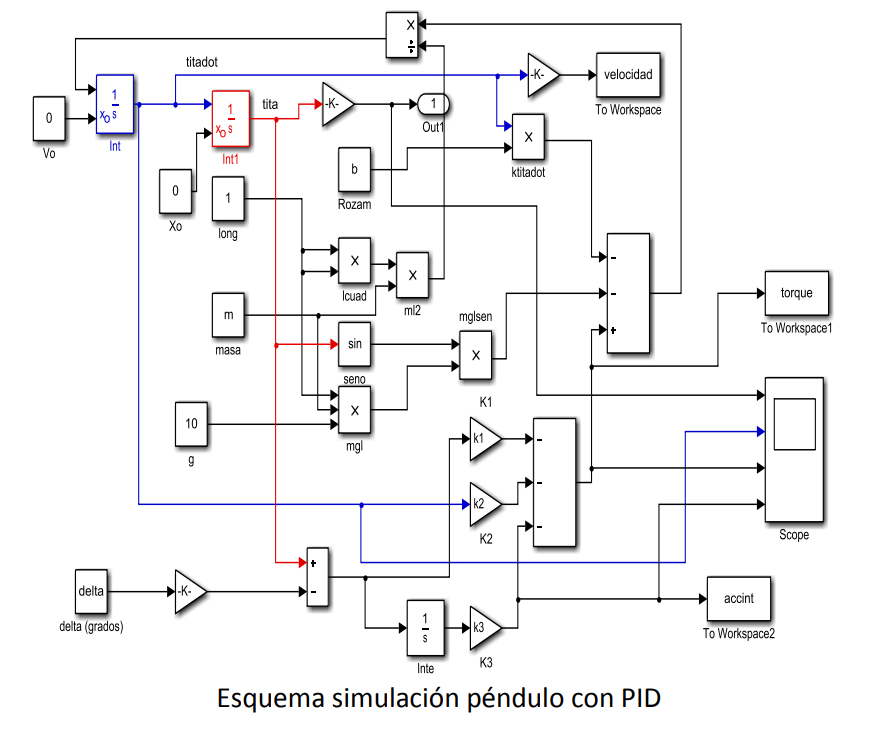

sim('pendulo_pid_tarea')

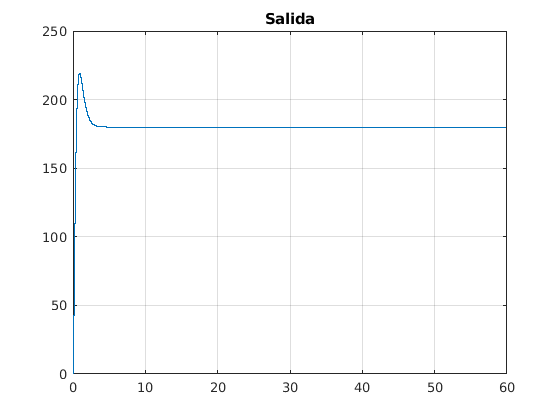

figure(1), plot(tout,yout)
grid on, title('Salida')

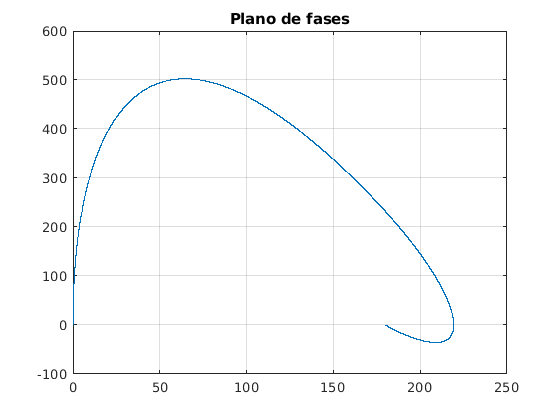

figure(2), plot(yout,velocidad) %plano de fase
grid on, title('Plano de fases')

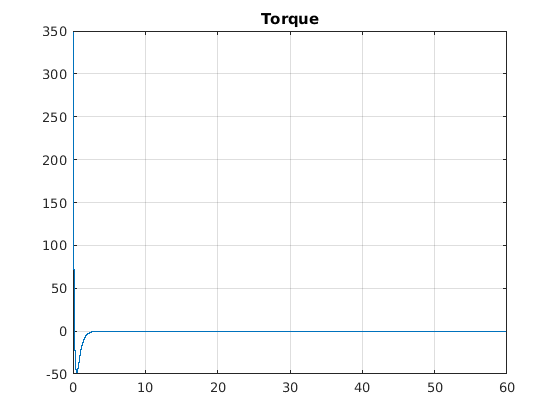

figure(3), plot(tout,torque) % torque total
grid on, title('Torque')

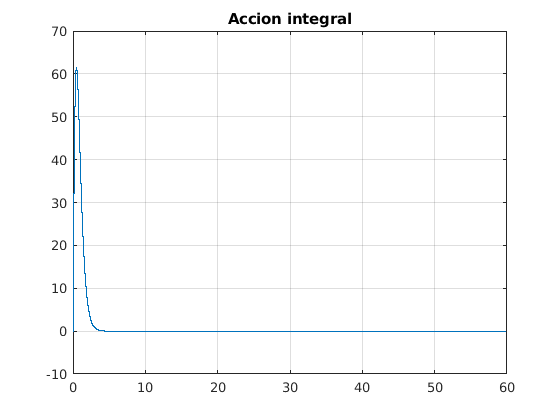

figure(4), plot(tout,-accint) % acción integral
grid on, title('Accion integral')

ymax=max(yout) % máximo valor de salida

ymax = 219.2768

S=(ymax-delta)/delta*100 % sobrepaso en %

S = 21.8205

erel=(delta-yout)/delta; %error relativo
efinal=erel(end) % error final, debe ser cero

efinal = 0

ind=find(abs(erel)>.02); % índice elementos con error relativo absoluto menor a 2%
tss=tout(ind(end)) % tiempo de establecimiento (ultimo valor del vector)

tss = 2.5239

yte=yout(ind(end)) % salida al tiempo ts

yte = 183.6001

uf=torque(end) % torque final

uf = 3.6739e-15

Intf=-accint(end) % acción integral final

Intf = -5.9916e-11

Se puede observar que el controlador cumple el objetivo planteado de estabilizar el pendulo en $\delta = 180º$

**Analizar la robustez variando la masa del péndulo en mas y menos 10% analizar los nuevos valores de sobrepaso, tiempo de establecimiento y acción de control final, elaborar una tabla con los resultados para los distintos valores de masa**

Se analiza la robustes para una masa 10% más pequeña.

% para analizar robustez
mnom=m % masa nominal

mnom = 3

m=0.9*mnom 

m = 2.7000

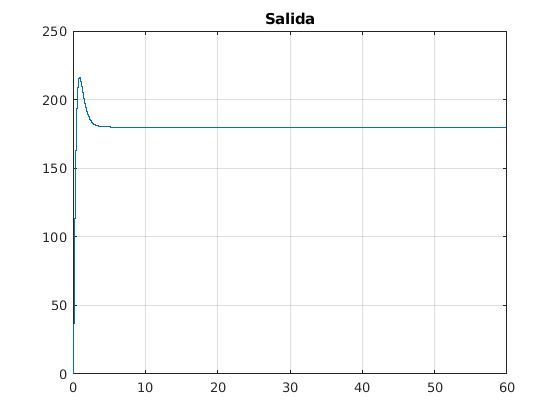


sim('pendulo_PID_tarea')
figure(1), plot(tout,yout)
grid on, title('Salida')

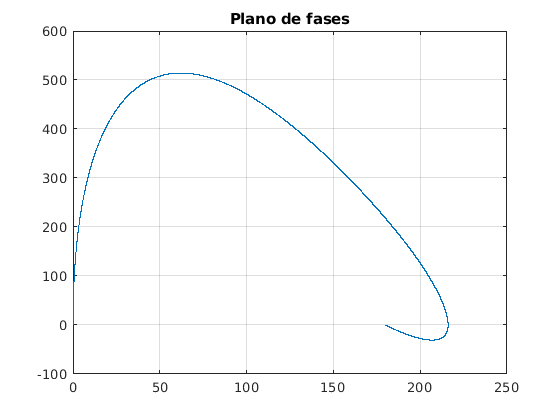

figure(2), plot(yout,velocidad) %plano de fase
grid on, title('Plano de fases')

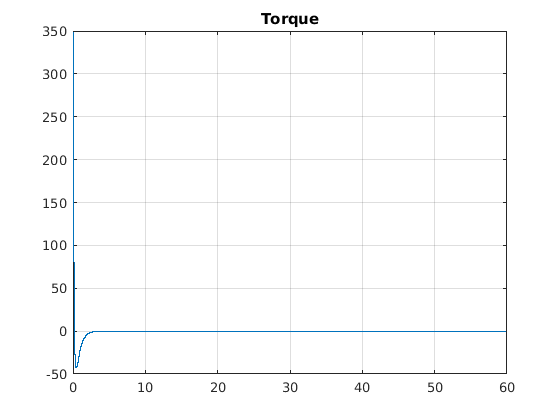

figure(3), plot(tout,torque) % torque total
grid on, title('Torque')

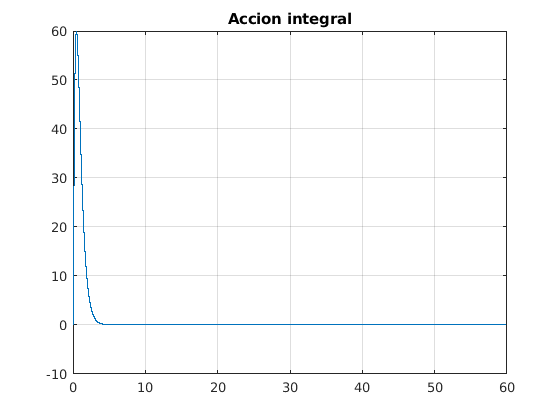

figure(4), plot(tout,-accint) % acción integral
grid on, title('Accion integral')

ymax=max(yout) % máximo valor de salida

ymax = 216.0619

S=(ymax-delta)/delta*100 % sobrepaso en %

S = 20.0344

erel=(delta-yout)/delta; %error relativo
efinal=erel(end) % error final, debe ser cero

efinal = 0

ind=find(abs(erel)>.02); % índice elementos con error relativo absoluto menor a 2%
tss=tout(ind(end)) % tiempo de establecimiento (ultimo valor del vector)

tss = 2.6252

yte=yout(ind(end)) % salida al tiempo ts

yte = 183.6006

uf=torque(end) % torque final

uf = 3.3065e-15

Intf=-accint(end) % acción integral final

Intf = -5.9915e-11

Si se repiten las simulaciones, para una masa 10% más grande, se obtiene

m=1.1*mnom % ídem

m = 3.3000

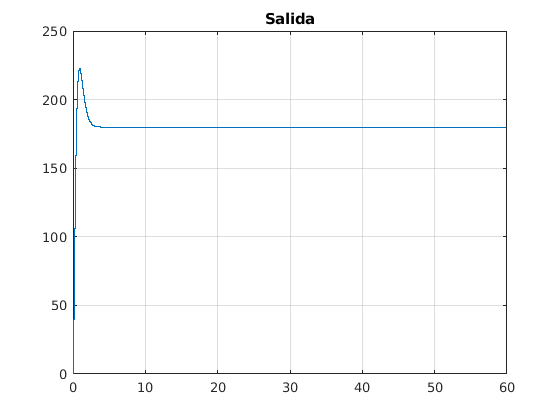


sim('pendulo_PID_tarea')
figure(1), plot(tout,yout)
grid on, title('Salida')

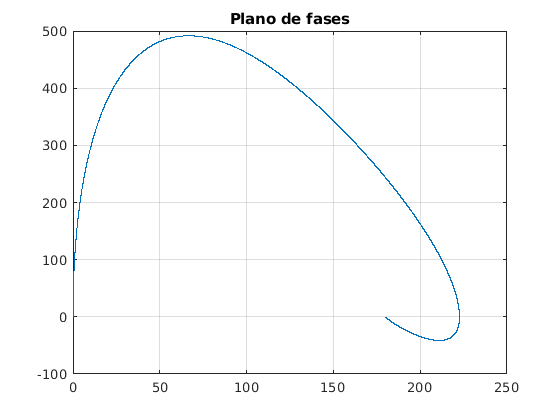

figure(2), plot(yout,velocidad) %plano de fase
grid on, title('Plano de fases')

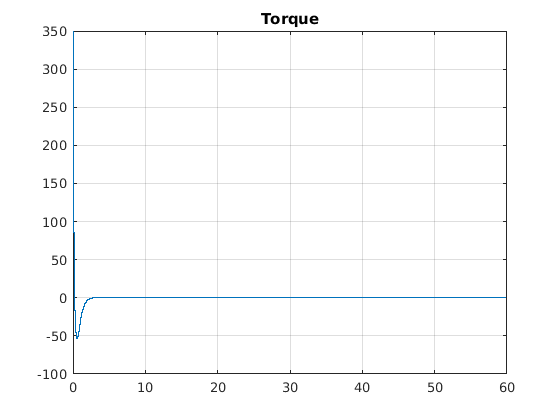

figure(3), plot(tout,torque) % torque total
grid on, title('Torque')

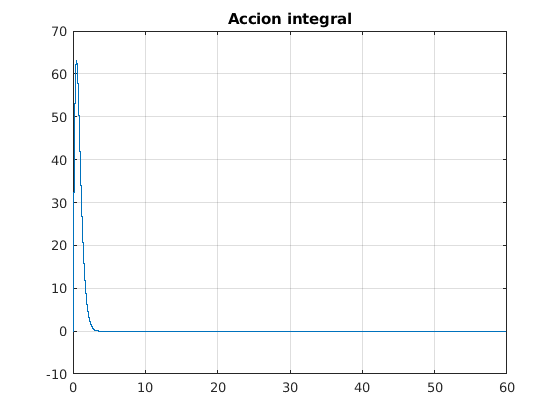

figure(4), plot(tout,-accint) % acción integral
grid on, title('Accion integral')

ymax=max(yout) % máximo valor de salida

ymax = 222.6486

S=(ymax-delta)/delta*100 % sobrepaso en %

S = 23.6937

erel=(delta-yout)/delta; %error relativo
efinal=erel(end) % error final, debe ser cero

efinal = 0

ind=find(abs(erel)>.02); % índice elementos con error relativo absoluto menor a 2%
tss=tout(ind(end)) % tiempo de establecimiento (ultimo valor del vector)

tss = 2.4161

yte=yout(ind(end)) % salida al tiempo ts

yte = 183.6008

uf=torque(end) % torque final

uf = 4.0413e-15

Intf=-accint(end) % acción integral final

Intf = -5.9918e-11

**Comparación de resultados**

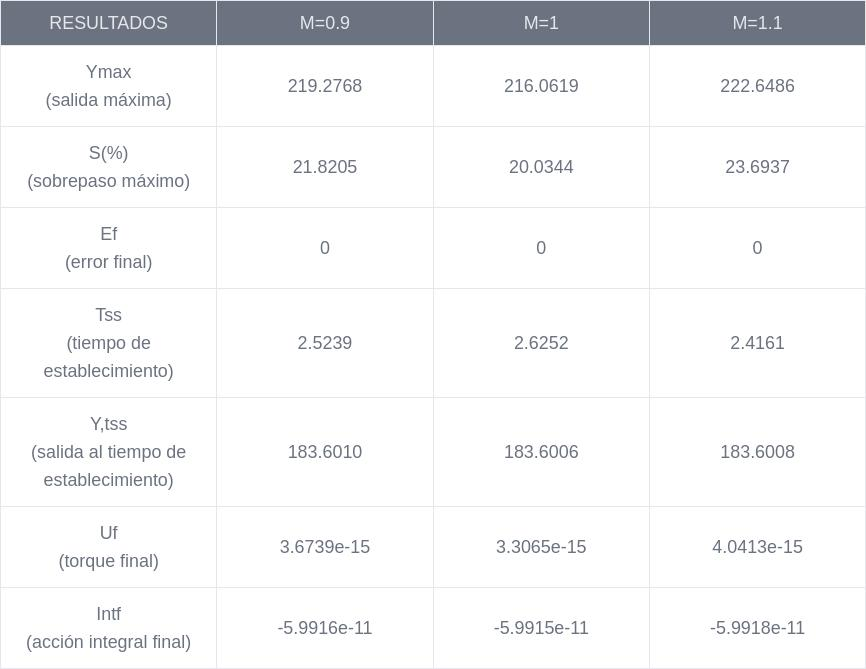

Se puede concluir, segun la tabla de los resultados obtenidos, que el sistema no es muy robusto por los siguientes motivos:

- El sobrepaso máximo aumentó en casi un 1.9% para la masa mayor y dismuyó en casi 1.8% para la masa menor. Lo cual es una variación casi 5 veces menor a la del cambio de masa.

- El tiempo de establecimiento aumento y disminuyo en 0.1 segundos para la masa mayor y menor respectivamente, lo cual representa un valor del 4% del tiempo de establecimiento original.

Dependiendo los requisitos de la aplicación, el controlador puede funcionar correctamente o no. Se destaca que gracias a la presencia del componente integrador, se logra un error final de 0 para todos los casos. Además, el torque final sube conforme aumentamos la masa, como era de esperarse.